clc; clear all; close all;

% This is Hydraulic System number 1 . rho (density) = 875 kg/m^3 . beta (bulk modulus) = 1100 MPa . Minimum gauge pressure (vacuum) = -1 bar , Qs01 = 60 l/min , V1 = 5913 cm^3 , V2 = 296 cm^3 , V3 = 5488 cm^3 , Cd1 = 0.87 , Ad01 = 25 mm^2 , Cd2 = 0.67 , Ad2 = 3 mm^2 , Cd3 = 0.49 , Ad3 = 5 mm^2 , Cd4 = 0.50 , Ad4 = 5 mm^2 , tRU1 = 166 milliSeconds , tH1 = 1138 milliSeconds , tRD1 = 166 milliSeconds , p1 (initial value) = 0 bar , p2 (initial value) = 0 bar , p3 (initial value) = 0 bar , simulation time = 1636 milliSeconds . What is the maximum absolute value of the p2 pressure [bar] ?

rho = 875; % kg/m^3
beta = 1100*10^6; % Pa

gauge_min = -1*10^5; % Pa

Qs01 = 60 * (10^-3 / 60); % m^3/s
V1 = 5913*10^-6; % m^3
V2 = 296*10^-6; % m^3
V3 = 5488*10^-6; % m^3
Cd1 = 0.87;
Ad01 = 25*10^-6; % m^2
Ad1 = 0;
Cd2 = 0.67;
Ad2 = 3*10^-6; % m^2
Cd3 = 0.49;
Ad3 = 5*10^-6; % m^2
Cd4 = 0.50;
Ad4 = 5*10^-6; % m^2

tRU1 = 166/1000; % s
tH1 = 1138/1000; % s
tRD1 = 166/1000; % s

p1 = 0; % Pa
p2 = 0; % Pa
p3 = 0; % Pa

simTime = 1636/1000; % s

t = 0; % s
dt = 10^-5; % s
idx = 1;

while(t <= simTime)
    % Calculation
    if(t<tRU1)
    Ad1 = 0;
    elseif(t < 2*tRU1)
        Ad1 = Ad01*(t-tRU1)/tRU1;
    else
        Ad1 = Ad01;
    end
    
    if(t <= tRU1)
        Qs1 = t/tRU1 * Qs01;
    elseif(t <= tRU1 + tH1)
        Qs1 = Qs01;
    elseif(t <= tRU1 + tH1 + tRD1)
        tm = t-(tH1+tRD1);
        Qs1 = Qs01 * (1-(tm/tRD1));
    else
        Qs1 = 0;
    end

    % Calculate flows
    Q2 = Cd2 * Ad2 * sign(p2-p1)*sqrt(2/rho*abs(p2-p1));
    Q3 = Cd3 * Ad3 * sign(p2-p3)*sqrt(2/rho*abs(p2-p3));
    Q4 = Cd4 * Ad4 * sign(p2-gauge_min)*sqrt(2/rho*abs(p2-gauge_min));
    Q5 = Cd1 * Ad1 * sign(p1-p3)*sqrt(2/rho*abs(p1-p3));
    % Calulate p dots
    p1Dot = beta/V1 * (Q2 - Q5);
    p2Dot = beta/V2 * (Qs1 - Q2 - Q3 - Q4);
    p3Dot = beta/V3 * (Q5 - Q3);
    % Logging
    tplt(idx) = t;
    Ad1plt(idx) = Ad1;
    Qs1plt(idx) = Qs1;
    p2plt(idx) = p2;

    % Time integration
    p1 = p1 + p1Dot * dt;
    p2 = p2 + p2Dot * dt;
    p3 = p3 + p3Dot * dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(tplt, p2plt/10^5)
grid

p2max = max(p2plt)/10^5

p2max =           77.0441876229035


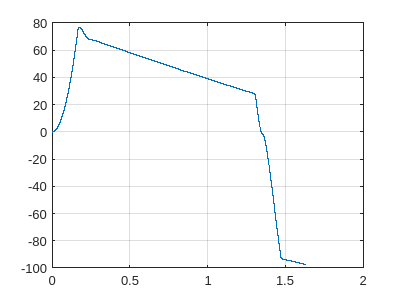


hold off

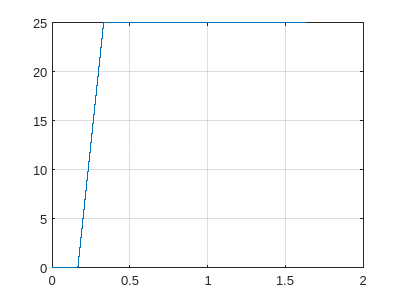

plot(tplt, Ad1plt*10^6)
grid
hold off

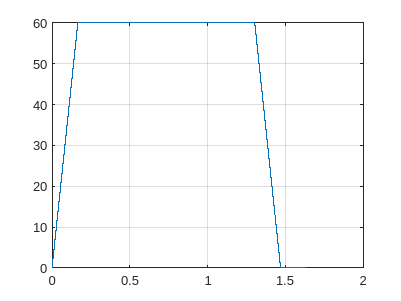

plot(tplt, Qs1plt*60*10^3)
grid

disp("What is the maximum absolute value of the p2 pressure [bar] ?")

What is the maximum absolute value of the p2 pressure [bar] ?
